[fname, fpath] = uigetfile('*.csv');
fullPath = fullfile(fpath,fname);
data = readtable(fullPath);
disp('file imported! processing...')

file imported! processing...


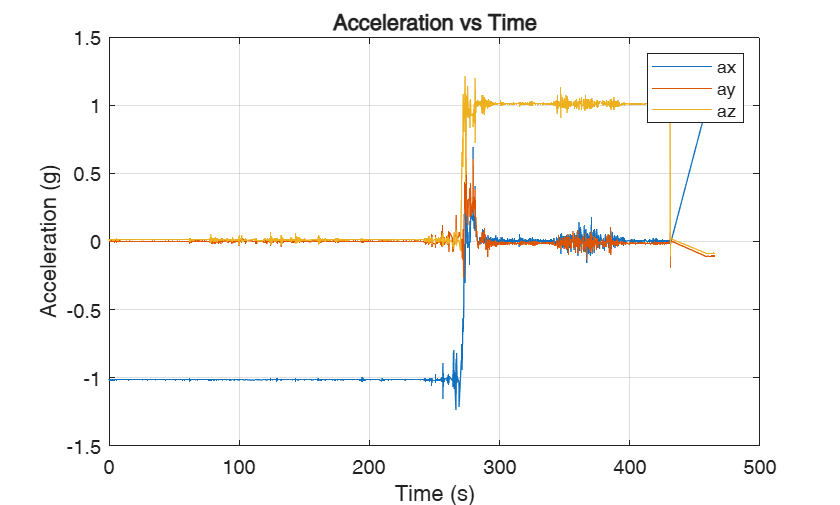


% data = readtable("C:\Users\xwkwx\Documents\GitHub\microgravity_dt\data\drop_log_2026-06-03_16-35-52.csv");

t = (data.ts_ms - data.ts_ms(1)) / 1000;
imu_t = data.imu_temp_c;
esp_t =  data.esp32_temp_c;
data.az_g = data.az_g*(-1);

% acceleration per axis
figure;
a_mag = sqrt(data.ax_g.^2 + data.ay_g.^2 + data.az_g.^2);

plot(t, data.ax_g, t, data.ay_g, t, data.az_g);
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Acceleration vs Time');
legend('ax','ay','az');
grid on;

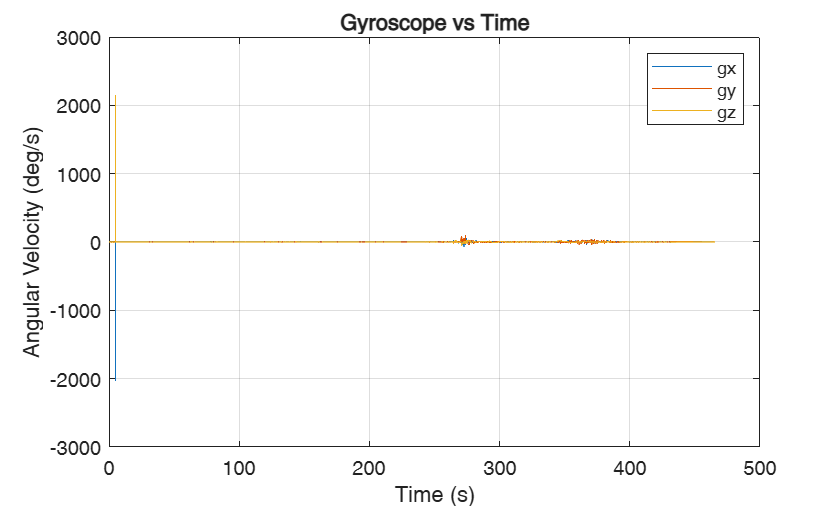


% gyroscope
figure;
plot(t, data.gx_dps, t, data.gy_dps, t, data.gz_dps);
xlabel('Time (s)');
ylabel('Angular Velocity (deg/s)');
title('Gyroscope vs Time');
legend('gx','gy','gz');
grid on;

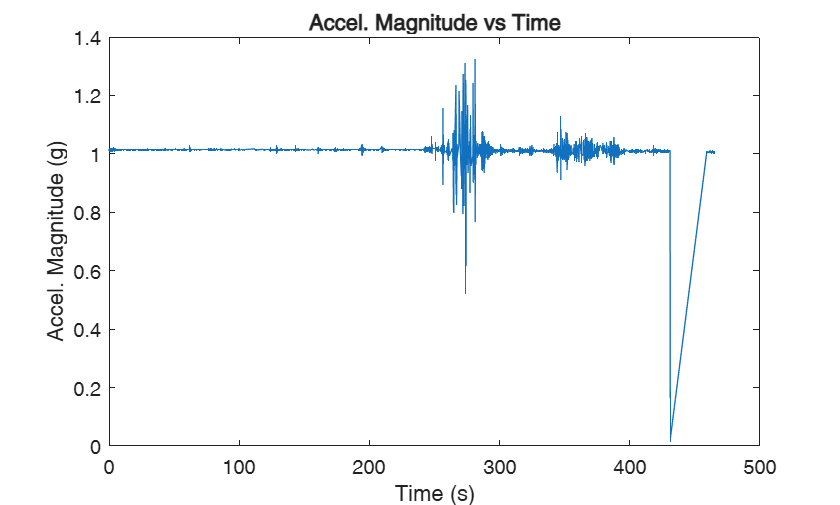


% acceleration magnitude
figure
plot(t,a_mag)
xlabel('Time (s)');
ylabel('Accel. Magnitude (g)');
title('Accel. Magnitude vs Time');

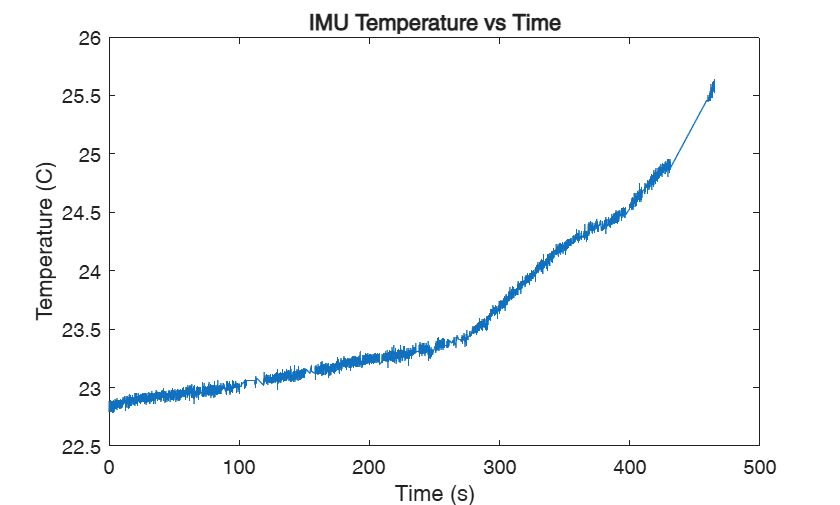


% imu temperature
figure
plot(t,imu_t)
xlabel('Time (s)');
ylabel('Temperature (C)')
title('IMU Temperature vs Time');

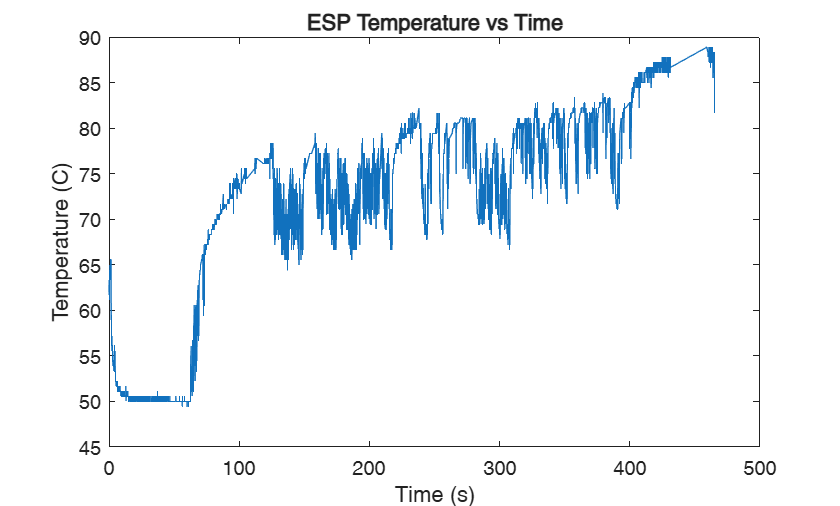


% esp32 temperature
figure
plot(t,esp_t)
xlabel('Time (s)');
ylabel('Temperature (C)')
title('ESP Temperature vs Time');